# Algoritmos Numéricos por Computadora

# Segundo parcial - Primavera 2022

Rodrigo Plauchú Rodríguez

182671

Sube tu archivo resultado a Canvas antes de las 10am.

## Al correr tu script deben desplegarse los resultados.

1. Demuestra que el algoritmo de Gauss-Seidel puede escribirse como


$$x_{i+1} =Tx_i +c$$


donde `T` es:


$$-{\left(D+L\right)}^{-1} \;U$$


y `c` es 


$${\left(D+L\right)}^{-1} \;b$$


Pega aquí tu respuesta.

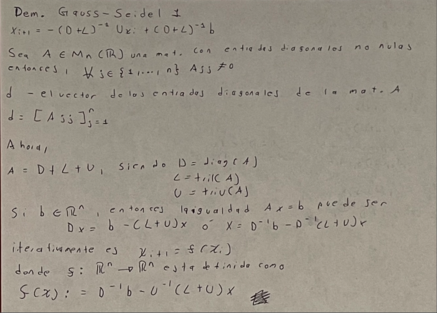

2.Codifica de manera eficiente, al final del script, el método esPositivaDefinida(A) empleando el criterio de [Sylvester](https://en.wikipedia.org/wiki/Sylvester%27s_criterion) y la función `det` de MATLAB.

3. Utiliza el método codificado en la pregunta anterior para determinar si la matriz A es positiva definida. Plan B (con penalización): puedes usar una línea de código para responder esta pregunta directamente.

A = [10,-1,2,0;-1,11,-1,3;2,-1,10,-1;0,3,-1,8];
res = SylvesterCrit(A);
if res == 1
    disp("True")
else
    disp("False")
end

True


4. Escribe, al final del script, la función  `gradiente(f,x,h)` que calcula numéricamente el gradiente de la función escalar $f:R^n \to R$ en el vector $x$. La función debe utilizar el método de diferencias centrales con paso $h$.

Prueba la función calculando el gradiente de $f\left(x,y,z\right)=5x^3 yz^2$en el punto `p`=[1;2;3] con `h`=0.0001.

f = @(x) 5*x(1)^3*x(2)*x(3)^2

f = function_handle with value:
    @(x)5*x(1)^3*x(2)*x(3)^2


h = 0.0001

h = 1.0000e-04

x = 1

x = 1

%grad = gradiente(f, x, h)

5. Utiliza tu algoritmo de Gauss-Seidel (cópialo más abajo) para resolver el sistema Ax = b, donde:


$$A=\left\lbrack \begin{array}{ccc}
0\ldotp 1 & 7 & -0\ldotp 3\\
3 & -0\ldotp 1 & -0\ldotp 2\\
0\ldotp 3 & -0\ldotp 2 & 10
\end{array}\right\rbrack$$



$$b=\left\lbrack \begin{array}{c}
-19\ldotp 3\\
7\ldotp 85\\
71\ldotp 4
\end{array}\right\rbrack$$


A = [0.1,7,-0.3; 3,-0.1,-0.2; 0.3,-0.2,10]

A =     0.1000    7.0000   -0.3000
    3.0000   -0.1000   -0.2000
    0.3000   -0.2000   10.0000


b = [-19.3;7.85;71.4]

b =   -19.3000
    7.8500
   71.4000


Dado que `A` no es estrictamente diagonal dominante, primero intercambia los renglones 1 y 2 de `A` y de `b` utilizando una matriz `P` de permutación (o un vector `p `de permutación)

Escribe aquí la matriz P de permutación (o el vector `p`)

P=[0,1,0;1,0,0;0,0,1]

P =      0     1     0
     1     0     0
     0     0     1


Intercambia los renglones de A y de b usando la matriz P  (o el vector `p`)

PA=P*A

PA =     3.0000   -0.1000   -0.2000
    0.1000    7.0000   -0.3000
    0.3000   -0.2000   10.0000


Pb=P*b

Pb =     7.8500
  -19.3000
   71.4000


Ya con lo renglones intercambiados, usa el método de Gauss-Seidel para resolver el sistema de ecuaciones.

[x,i]=gaussSeidelEleg(PA,Pb)

x =     3.0000
   -2.5000
    7.0000


i = 9

6. Utilizando un método iterativo (que debes pegar más abajo) resuelve el siguiente sistema de ecuaciones en 3 o menos iteraciones.

A = [4,-1,0;-1,4,-1;0,-1,4]

A =      4    -1     0
    -1     4    -1
     0    -1     4


b = [2;6;2]

b =      2
     6
     2


x=zeros(3,1)

x =      0
     0
     0


[x,i]=GradienteConjugadoEleg(A,b,x)

x =      1
     2
     1


i = 2

7. Usando el método de Newton-Raphson de varias variables (que debes pegar abajo) encuentra un punto en común de tres [esferas](https://es.wikipedia.org/wiki/Esfera#Ecuaciones_de_la_esfera) de radio 5 con centros en  (1,-2,0), (-2,2,-1), y (4,-2,3).

Considera como valor inicial x0=[-1;-1;-1]

ec. esfera: $x^2 +y^2 +z^2 =5$

f=@(x) [(x(1)-1)^2+(x(2)+2)^2+(x(3)-0)^2-5;
        (x(1)+2)^2+(x(2)-2)^2+(x(3)+1)^2-5;
        (x(1)-4)^2+(x(2)+2)^2+(x(3)-3)^2-5]

f = function_handle with value:
    @(x)[(x(1)-1)^2+(x(2)+2)^2+(x(3)-0)^2-5;(x(1)+2)^2+(x(2)-2)^2+(x(3)+1)^2-5;(x(1)-4)^2+(x(2)+2)^2+(x(3)-3)^2-5]


J=@(x) [2*x(1)-2,2*x(2)+4,2*x(3);
        2*x(1)+4,2*x(2)-4,2*x(3)+2;
        2*x(1)-8,2*x(2)+4,2*x(3)-6]

J = function_handle with value:
    @(x)[2*x(1)-2,2*x(2)+4,2*x(3);2*x(1)+4,2*x(2)-4,2*x(3)+2;2*x(1)-8,2*x(2)+4,2*x(3)-6]


[x1,~]=NewtonRaphsonVVEleg(f,J,[-1;-1;-1])

x1 =     3.1043
    3.0522
    0.8957


Escribe aquí tu función esPositivaDefinida(A).

Puedes suponer que la matriz A es cuadrada.

function res = SylvesterCrit(A)
res= true;
[tam1,tam2]=size(A);
if tam1==tam2    
   i=1;
    while(res && i<= tam1)
        if det(A(i,i))<=0
        res=false;
        end
    i=i+1;
    end 
end
end

Escribe aquí tu función gradiente

function g = gradiente(f, x, h)
    syms t; 
    i=0;
    MAX=80;
    TOL=eps();
    do = true;
    while do
        i=i+1
        dx0 = centralFirstDerivative(f,x,h);
        x0=x+(dx0)*t; 
        ft=f(x0(1));
        tsym= sym(ft);
        dts=diff(tsym);
        dt = matlabFunction(dts);
        tE=solve(dt,t);
        x=x+tE*(dx0);

        do=abs(dx0)>eps;
    end
end

function y = centralFirstDerivative(f,x,h)
    h=1;
    i=1;
    n=length(f);
    dfs= diff(fx);
    df=matlabFunction(dfs);
    dfact=df(x);
    
    while i<Max
        der(i)=(f(x+h)-f(x-h))/(2*h);
        i=i+1;
    end
end

Copia aquí tu funcion Gauss-Seidel

function [x,i] = gaussSeidelEleg(A,b)
    if ~isDiagDom(A)
        warning('La matriz no es diagonalmente dominante')
    end
    tol=eps;
    MAXi=1000;
    i=0;
    x=zeros(size(b));
    D=diag(diag(A));
    L=tril(A,-1);
    M=D+L;
      
    do=true;
    while do 
        xp=x;
        r=b-A*x;
        x=x+M\r;
        i=i+1;
        do=norm((x-xp)./x,Inf)>tol && i<MAXi;  
    end    
end

function res= isDiagDom(A)
   res=true;
   [m,n]=size(A);
   if m~=n, error('La matriz no es cuadrada'), end
   
   i=1;
   while res && i<n
       res=abs(A(i,i))>sum(abs(A(i,[1:i-1 i+1:n])));
       i=i+1;
   end
end

Copia aquí tu función iterativa para resolver el problema 6

function [x, i] = GradienteConjugadoEleg(A, b, x)
    if ~PD(A)
        error('La matriz A no es positiva definida.');
    end
    
    max_iter = length(x);
    tol = eps();
    
    r = b - A * x;
    d = r;
    
    i = 0;
    cond = norm(r) ~= 0;
    while cond
        xp = x;
        rr = dot(r, r);
        alpha = rr / (d' * A * d);
        
        x = x + alpha * d;
        r = b - A * x;
        d = r + (dot(r, r) / rr) * d;
        
        i = i + 1;
        cond = norm(r) ~= 0 && norm((x - xp) / x, inf) > tol && i < max_iter;
    end
end

function res = PD(A)
    [m, n] = size(A);
    res = m == n && all(eig(A) > 0) && issymmetric(A);
end

Copia aquí tu función de Newton-Raphson de varias variables

function [x,i] = NewtonRaphsonVVEleg(f,J,x)
    i=0;
    MAX=80;
    TOL=eps();
    fx=f(x);
    do = true;
    
    while do
        xp=x;
        x=xp-J(xp)\fx;
        fx=f(x);
        i=i+1;
        do = i<MAX  && any(fx) && norm((x-xp)./x,inf)>TOL;
    end
end